***Definições Iniciais***

rng(1);
% Qtd de Seções delay = Qtd de Subportadoras
M=16;
% Qtd de Seções Doppler = Qtd de Slots de Tempo
N=16;
% Banda das Subportadoras
df=15e3;
% Duração de um bloco
dT=1/df;
% Portadora
fc=4e9;
% Resolução do Grid OTFS
delayResolution = 1/(M*df);
dopplerResolution = 1/(N*dT);
% Transformada de Fourier Discreta
Fn=dftmtx(N);
Fn=Fn/norm(Fn);
%
c = physconst('Lightspeed');

***Criação do Frame OTFS***

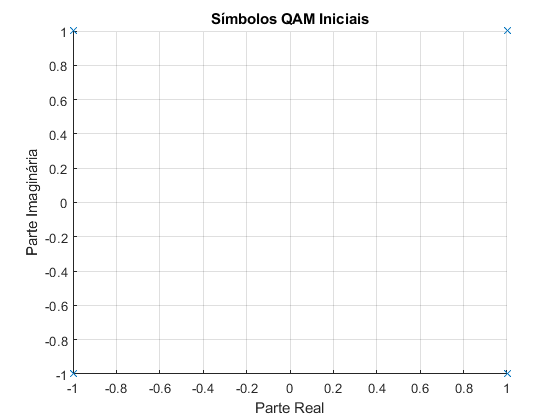

% Qtd de Símbolos
qtySyms=4;
% Qtd de Símbolos por Frame
qtySymsPerFrame=N*M;
% Qtd de Bits por Frame
qtyBitsPerFrame=qtySymsPerFrame*log2(qtySyms);
% Geração dos bits p/ transmissão
txBits=randi([0,1],qtyBitsPerFrame,1);
% Bits em Símbolos - Código Gray
txSyms=qammod(txBits,qtySyms,'gray','InputType','bit');
% Matriz X de Símbolos
X=reshape(txSyms,M,N);

figure;
scatter(real(txSyms), imag(txSyms), 'x');
title('Símbolos QAM Iniciais');
xlabel('Parte Real');
ylabel('Parte Imaginária');
grid on;

***Modulação OTFS***

% Aplicação ISFFT (OTFS) + DFT (OFDM)
Xtil=X*Fn';
% Sinal a ser transmitido
s=reshape(Xtil,1,N*M);

***Canal 3GPP EVA***

delaysEVA = [0, 30, 150, 310, 370, 710, 1090, 1730, 2510]*1e-9;
dBEVA = [0.0, -1.5, -1.4, -3.6, -0.6, -9.1, -7.0, -12.0, -16.9];

% Vel. Máx. UE
maxUEVelKmh=500;
maxUEVel = maxUEVelKmh*1000*1/60*1/60;

% Potência dB -> Linear normalizado
linearEVA = 10.^(dBEVA/10);
linearEVA = linearEVA/sum(linearEVA);
% Caminhos de propagação
taps=length(delaysEVA);
% Coeficientes de Ganho (Rayleigh fading)
gains = sqrt(linearEVA).*(sqrt(1/2) * (randn(1,taps)+1i*randn(1,taps)));
% Coeficientes de Delay
delays = round(delaysEVA./delayResolution);
% Doppler Spread Máximo Normalizado
nuMax = maxUEVel*fc/c;
nuMax = nuMax/dopplerResolution;
% Coeficientes de Doppler Shift (Jakes Spectrum)
dopplerShifts = (nuMax*cos(2*pi*rand(1,taps)));
% Delays distintos
uniqueDelays = unique(delays);

***Resposta ao Impulso "gs" e Canal no tempo "G"***

z=exp(1i*2*pi*1/M*1/N);
% Resposta ao Impulso Discreta - g^s
gs=zeros(length(uniqueDelays),N*M);
for q=1:N*M
  for i=1:taps
    gs(delays(i)+1,q)=gs(delays(i)+1,q)+gains(i)*z^(dopplerShifts(i)*((q-1) - delays(i)));
  end
end
% Matriz do Canal no Tempo - G
G=zeros(N*M,N*M);
for q=1:N*M
  for l=(uniqueDelays+1)
    if(q>=l)
      G(q,q-l+1)=gs(l,q);
    end
  end
end

***Transformação do sinal "s" pelo canal***

r=zeros(N*M,1);
for q=1:N*M
  for l=(uniqueDelays+1)
    if(q>=l)
      r(q)=r(q)+gs(l,q)*s(q-l+1);
    end
  end
end
snrdB = 5; 
r = awgn(r, snrdB);
variance = var(r);

***Demodulação OTFS***

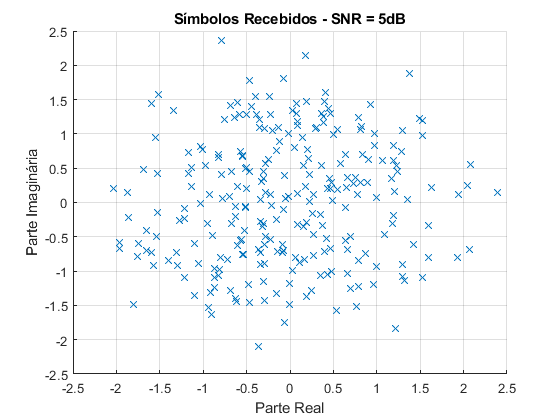

Ytil=reshape(r,M,N);
% Aplicação IDFT (OFDM) + SFFT (OTFS)
Y=Ytil*Fn;
% Símbolos delay-Doppler afetados pelo canal
y=reshape(Y.',N*M,1);

figure;
scatter(real(y), imag(y), 'x');
title('Símbolos Recebidos - SNR = 5dB');
xlabel('Parte Real');
ylabel('Parte Imaginária');
grid on;

***Detecção MMSE***

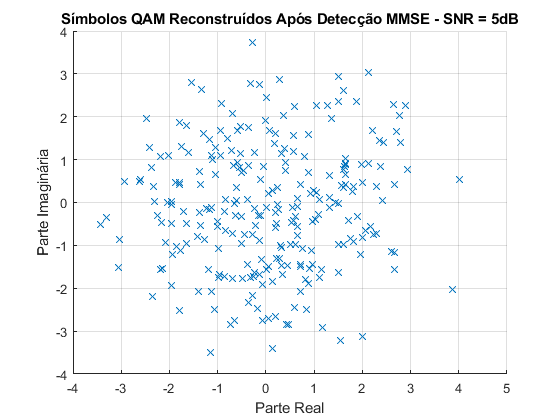

% Detecção MMSE no TEMPO
XtilHat = reshape((G'*G+variance)\(G'*r), M, N);
% Aplicação IDFT (OFDM) + SFFT (OTFS)
Xhat = XtilHat*Fn;
xHatSyms = reshape(Xhat,N*M,1);
xHatBits = qamdemod(xHatSyms, qtySyms, 'gray', 'OutputType', 'bit'); 

figure;
scatter(real(xHatSyms), imag(xHatSyms), 'x');
title('Símbolos QAM Reconstruídos Após Detecção MMSE - SNR = 5dB');
xlabel('Parte Real');
ylabel('Parte Imaginária');
grid on;

***BER***

ber = sum(txBits ~= xHatBits)/length(txBits)

ber = 0.1816

***Gráfico de BER***

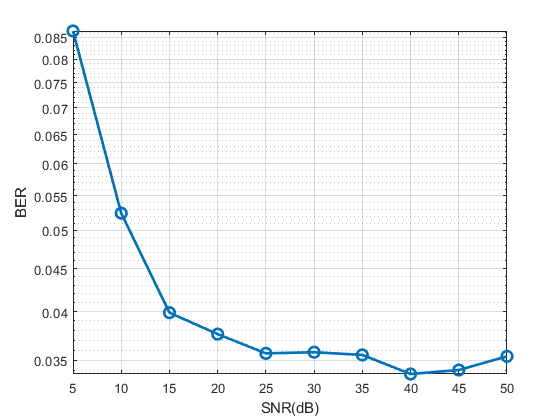

snr = 5:5:50;
qtyFrames = 1000;
BER = zeros(1,length(snr));
meanBER = zeros(1,length(snr));

for snrIdx = 1:length(snr)
    for frameIdx = 1:qtyFrames
        %current_frame_number(iesn0)=ifram;
        qtySymsPerFrame=N*M;
        % Qtd de Bits por Frame
        qtyBitsPerFrame=qtySymsPerFrame*log2(qtySyms);
        % Geração dos bits p/ transmissão
        txBits=randi([0,1],qtyBitsPerFrame,1);
        % Bits em Símbolos - Código Gray
        txSyms=qammod(txBits,qtySyms,'gray','InputType','bit');
        % Matriz X de Símbolos
        X=reshape(txSyms,M,N);
        
        % Aplicação ISFFT (OTFS) + DFT (OFDM)
        Xtil=X*Fn';
        % Sinal a ser transmitido
        s=reshape(Xtil,1,N*M);
        
        % Coeficientes de Ganho (Rayleigh fading)
        gains = sqrt(linearEVA).*(sqrt(1/2) * (randn(1,taps)+1i*randn(1,taps)));
        % Coeficientes de Delay
        delays = round(delaysEVA./delayResolution);
        % Doppler Spread Máximo Normalizado
        nuMax = maxUEVel*fc/c;
        nuMax = nuMax/dopplerResolution;
        % Coeficientes de Doppler Shift (Jakes Spectrum)
        dopplerShifts = (nuMax*cos(2*pi*rand(1,taps)));
        % Delays distintos
        uniqueDelays = unique(delays);

        % Resposta ao Impulso Discreta - g^s
        gs=zeros(length(uniqueDelays),N*M);
        for q=1:N*M
            for i=1:taps
                gs(delays(i)+1,q)=gs(delays(i)+1,q)+gains(i)*z^(dopplerShifts(i)*((q-1) - delays(i)));
            end
        end
        % Matriz do Canal no Tempo - G
        G=zeros(N*M,N*M);
        for q=1:N*M
            for l=(uniqueDelays+1)
                if(q>=l)
                    G(q,q-l+1)=gs(l,q);
                end
            end
        end
        r=zeros(N*M,1);
        for q=1:N*M
            for l=(uniqueDelays+1)
                if(q>=l)
                    r(q)=r(q)+gs(l,q)*s(q-l+1);
                end
            end
        end
        r = awgn(r, snr(snrIdx));
        variance = var(r);
        
        % Detecção MMSE no TEMPO
        % Regularização para evitar uma matriz não inversível
        lambda = 1e-9;
        A = G' * G + variance * eye(size(G, 2));
        XtilHat = reshape((A + lambda * eye(size(A))) \ (G' * r), M, N);
%         XtilHat = reshape((G'*G+variance)\(G'*r), M, N);
        % Aplicação IDFT (OFDM) + SFFT (OTFS)
        Xhat = XtilHat*Fn;
        xHatSyms = reshape(Xhat,N*M,1);
        xHatBits = qamdemod(xHatSyms, qtySyms, 'gray', 'OutputType', 'bit'); 
             
        % BER
        err = sum(xHatBits ~= txBits);
        BER(1,snrIdx) = BER(1,snrIdx) + err;
        meanBER(1,snrIdx) = BER(1,snrIdx)*1/length(txBits)*1/frameIdx;
    end 
end

figure(1)
semilogy(snr,meanBER,'o-','LineWidth',2,'MarkerSize',8)
grid on
xlabel('SNR(dB)')
ylabel('BER')